%0% Filenames
filenames_count = {};
RF12Pwr = [];

atoms_count = zeros(size(filenames_count));
for i = 1:length(filenames_count)
    temp = imagedata(filenames_count{i},'crop',{'rect',280,221,150,300},'bg',{'avg',20},'plot',{0}); %,'Nsat',630
    atoms_count(i) = sum(sum(temp.od2));
end

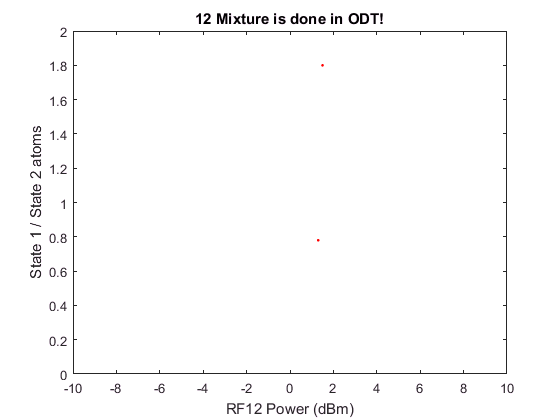

%% S1/S2 ratio
atoms_ratio = zeros(length(filenames_count)/2,1);
RF12Pwr2 = atoms_ratio;
for i = 1:1:length(atoms_ratio)
    atoms_ratio(i) = atoms_count(2*i-1) / atoms_count(2*i);
    RF12Pwr2(i) = RF12Pwr(2*i);
end

figure;
plot(RF12Pwr2,atoms_ratio,'r.'); ylim([0 2]); xlim([-10,10]); xlabel('RF12 Power (dBm)'); ylabel('State 1 / State 2 atoms'); title('12 Mixture is done in ODT!');